%% load data
load("data/processed/hodakaExp2022.mat");
exp = C;
load("data/processed/hodakaSite202309.mat");
site = C;


## see data

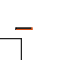

ips = 'ips10';
% experiment
figure; 
plot(exp.Qs, LineWidth=2); 
yyaxis right; plot(exp.(ips))
legend('Qs', ips)

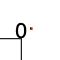


% site data
figure;
plot(site.date, site.Qs, LineWidth=2);
yyaxis right; plot(site.date, site.(ips))
legend('Qs', ips)

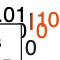

% site exp concat
load("data/processed/hodakaExpSiteConcat.mat")
figure;
plot(C.Qs, LineWidth=2);
yyaxis right; plot(C.ips5)
legend('Qs', 'ips5')

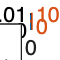

% site exp concat with logarithm
load("data/processed/hodakaExpSiteConcat.mat")
vMin = min(C.Qs(C.Qs~=0));
lnC = C.Qs/vMin;
lnC(lnC==0) = 0.1;
lnC = log(lnC);
plot(lnC)   